**Como crear objetos de clase in MATLAB**

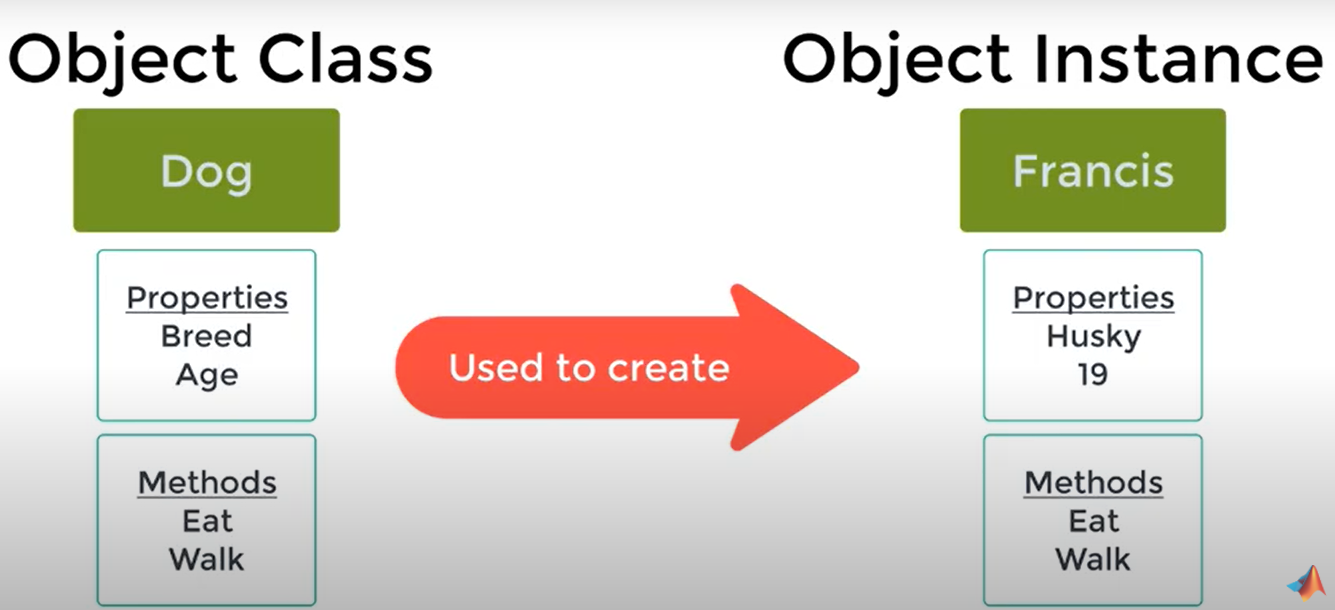

% Llamar al constructor de una clase y asigna a una variable
rSmall = Rect(1, 3)

rSmall =   Rect with properties:

    length: 1
     width: 3


rBig = Rect(10, 20)

rBig =   Rect with properties:

    length: 10
     width: 20


**Usando métodos de clases y accediendo a propiedades**

l = rSmall.length

l = 1

w = rBig.width

w = 20

a = rBig.area()

a = 200

**Arreglo de objetos**

rectArray = [Rect(2,2), Rect(3, 2), rSmall, rBig]

rectArray =   1×4 Rect array with properties:

    length
    width


% Creando un vector de longituades de rectángulos
rLengths = [rectArray.length]

rLengths =      2     3     1    10


rDoubleLengths = rLengths * 2

rDoubleLengths =      4     6     2    20


**Comparación entre clases Handle y Value**

Un constructor de clase de *valor* devuelve un objeto que está asociado con la variable a la que está asignado. Si reasigna esta variable, MATLAB ® crea una copia independiente del objeto original. *Si pasa esta variable a una función para modificarla, la función debe devolver el objeto modificado como un argumento de salida*. Para obtener información sobre el comportamiento de la clase de valor, consulte [Evitar copias innecesarias de datos](https://la.mathworks.com/help/matlab/matlab_prog/avoid-unnecessary-copies-of-data.html) .

Un constructor de clase de Handle devuelve un objeto identificador que es una referencia al objeto creado. Puede asignar el objeto de identificador a múltiples variables o pasarlo a funciones sin que MATLAB haga una copia del objeto original. Una función que modifica un objeto identificador pasado como argumento de entrada no necesita devolver el objeto.

Todas las clases de identificadores se derivan de la [`handle`](https://la.mathworks.com/help/matlab/ref/handle-class.html) clase abstracta .

**Crear una clase de valor**

Por defecto, las clases de MATLAB son clases de valor. La siguiente definición crea una clase de valor llamada "MiClaseDeValor"

`classdef`` MyValueClass `

   `...`

`end` 

ev = EsferoValue("bic", "azul", 0.5, 100, false)

ev =   EsferoValue with properties:

    modelo: "bic"
     color: "azul"
     punta: 0.5000
     carga: 100
    tapado: 0


ev.rayar()

Rayando


ev.tapar()

ans =   EsferoValue with properties:

    modelo: "bic"
     color: "azul"
     punta: 0.5000
     carga: 100
    tapado: 1


%ans.rayar()
ev = ev.tapar()

ev =   EsferoValue with properties:

    modelo: "bic"
     color: "azul"
     punta: 0.5000
     carga: 100
    tapado: 1


ev.rayar()

Error using EsferoValue/rayar (line 23)
No se puede rayar, el esfero está tapado

**Crear un Handle Class**

Para crear una clase hande, derivar la clase de la clase de handle.

`classdef`` MyHandleClass < handle`

   `...`

`end` 

eh = EsferoHandle("bic", "azul", 0.6, 90, false)

eh =   EsferoHandle with properties:

    modelo: "bic"
     color: "azul"
     punta: 0.6000
     carga: 90
    tapado: 0


eh.rayar()

Rayando........


eh.tapar()
eh

eh =   EsferoHandle with properties:

    modelo: "bic"
     color: "azul"
     punta: 0.6000
     carga: 90
    tapado: 1


eh.rayar()

Error using EsferoHandle/rayar (line 25)
No se puede rayar, el esfero está tapado

### `HERENCIA`

Una de las principales propiedades de las clases es la herencia. Esta propiedad nos permite crear nuevas clases a partir de clases existentes, conservando las propiedades de la clase original y añadiendo otras nuevas.

La nueva clase obtenida se conoce como clase derivada, y las clases a partir de las cuales se deriva, clases base. Además, cada clase derivada puede usarse como clase base para obtener una nueva clase derivada.

- Esto permite una gran cantidad de reutilización de código, y la posibilidad de crear jerarquías de clases para su aplicación (por ejemplo, la jerarquía de tipos de datos en MATLAB).

- Se puede pensar en la herencia de la clase B de la clase A como la aplicación de la semántica "B es una A" (que no debe confundirse con la con la clásica "B tiene una A").

- Estrechamente conectada está la idea del polimorfismo: una única interfaz se declina de múltiples formas, y la aplicación de speciﬁca es decidido sólo en tiempo de ejecución.